
% We simulate two virtual patients with triple-negative breast cancer
% who both get the same chemotherapy on Day 30:
%  ARM 1 (Control)    : constant feeding + chemo at Day 30
%  ARM 2 (Experiment) : fasts from Day 28 to Day 30, then chemo at Day 30
% Then we compare how big the tumor is in each. 

%    G = glucose
%    H = healthy cells
%    C = cancer cells

% Nutrient- Dependent Logistic Competition Model
% dG/dt = I(t) - alpha_H*G*H - alpha_C*G*C - delta_G*G
% dH/dt = lambda_H*G*H*(1 - (H+C)/K) - mu_H*H - killH*H
% dC/dt = lambda_C*G*C*(1 - (H+C)/K) - mu_C*C - killC*C

%  Run with tnbc_fasting_trial
%  Saves tnbc_results.mat for the visuals script.

clear; clc; close all;

p.G0      = 1.0;    % Glucose           
p.H0      = 1.0;    % Healthy cells      
p.C0      = 0.2;    % Cancer cells       

p.I_base  = 1.0;    % feeding rate while eating     
p.alpha_H = 0.1;    % healthy glucose uptake per cell
p.alpha_C = 0.5;    % cancer glucose uptake (5x healthy)
p.delta_G = 0.5;    % background glucose clearance  

p.lambda_H = 0.1;   % healthy glucose-dependent growth
p.lambda_C = 0.3;   % cancer growth (3x healthy)
p.K        = 1.5;   % tissue carrying capacity
p.mu_H     = 0.02;  % healthy natural apoptosis       
p.mu_C     = 0.02;  % cancer natural apoptosis      

p.killH   = 0.02;   % chemotherapy toxicity to healthy tissue    
p.killC   = 0.08;   % chemotherapy kill rate on tumour     

% the CONTROL arm uses killH / killC exactly as written here, whereas 
% the fasted EXPERIMENT arm is given sensitized chemo: 
% killH = 0.01 and killC = 0.12 for a full 48 h fast

p.tEnd     = 60;    % total simulation length                   
p.tChemo   = 30;    % day chemotherapy starts 
p.fastHrs  = 48;    % fast duration in hours            

%  Differential Stress Resistance 
%  during the fast only, healthy cells enter protected
%  maintenance mode and tumour cells suffer oxidative stress.

p.useDSR    = true;
p.dsrH      = 0.5;  % mu_H multiplier during fast (<1 = protected)
p.dsrC      = 4.0;  % mu_C multiplier during fast (>1 = stressed)

useLogY     = false;   % set true if your populations span orders of magnitude
runSweep    = true;    % sweep fast duration 0-96 h 

% Work out when the fast happens:
% fastHrs/24 converts 48 hours into 2 days.      
fastStart = p.tChemo - p.fastHrs/24;
fastEnd   = p.tChemo;

% Run the simulation with our function runArm 
% It returns TWO things:
%   tCon : a column of time points (days)
%   Ycon : a matrix with one row per time point and 3 columns:
%          column 1 = G, column 2 = H, column 3 = C

% ARM 1: control
[tCon, Ycon] = runArm(p, Inf, Inf);

% ARM 2: experiment
[tFas, Yfas] = runArm(p, fastStart, fastEnd);


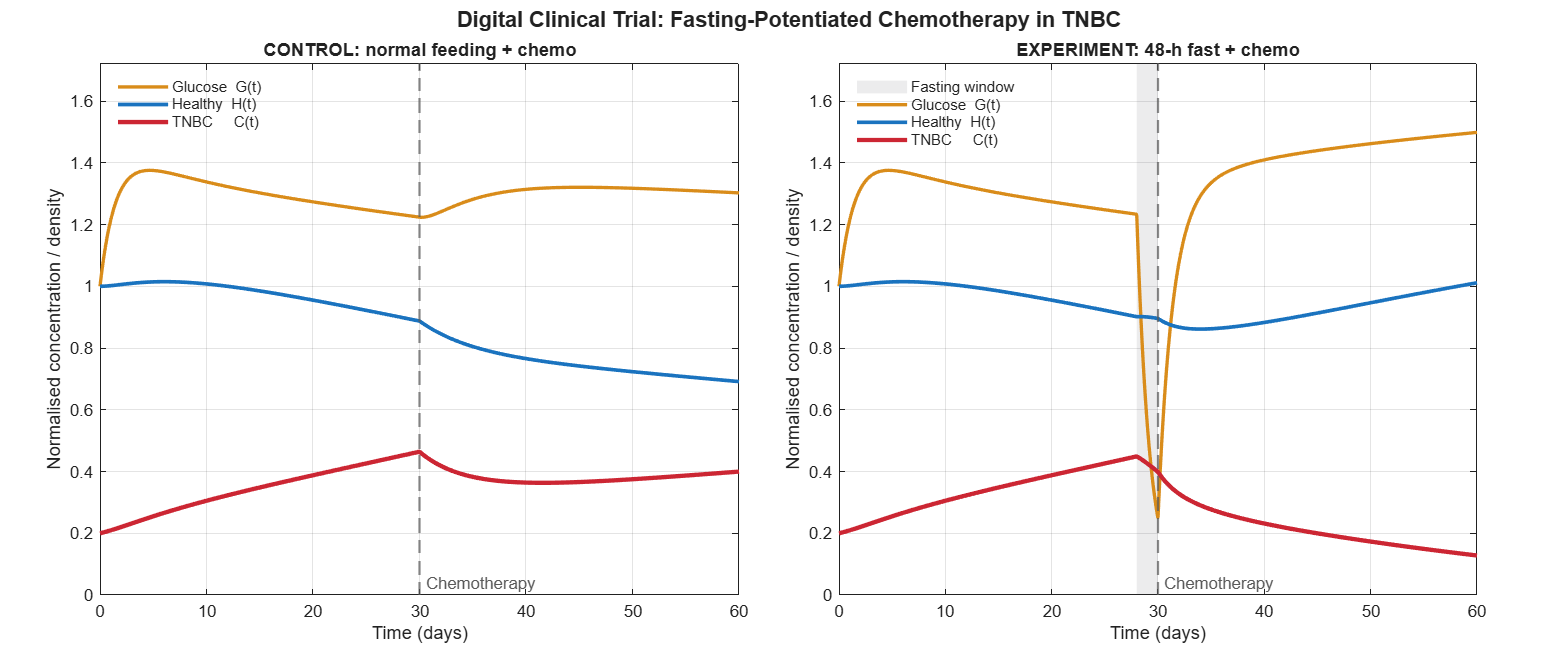


% Figure 1: 2-Panel Baseline comparison:

colG = [0.85 0.55 0.10];   
colH = [0.10 0.45 0.75];
colC = [0.80 0.15 0.20]; 

fig = figure('Color','w','Position',[80 80 1250 520]);
tl  = tiledlayout(fig,1,2,'TileSpacing','compact','Padding','compact');

% Each inner list is: {title, time vector, data matrix, show-fast-band?}
panels = { {'CONTROL: normal feeding + chemo', tCon, Ycon, false}, ...
           {sprintf('EXPERIMENT: %g-h fast + chemo',p.fastHrs), tFas, Yfas, true} };

for k = 1:2
    % Loop twice: k = 1 draws the CONTROL panel, k = 2 the EXPERIMENT panel.

    nexttile; hold on; box on;

    t = panels{k}{2};  Y = panels{k}{3};  showFast = panels{k}{4};
    % t = time points, Y = the G/H/C data, showFast = true/false.

    yl = [0 1.15*max([Ycon(:);Yfas(:)])];
    % Choose the y-axis range

    if showFast
        patch([fastStart fastEnd fastEnd fastStart], [yl(1) yl(1) yl(2) yl(2)], ...
              [0.25 0.25 0.30],'FaceAlpha',0.10,'EdgeColor','none', ...
              'DisplayName','Fasting window');
    end
    % patch(x, y, colour) draws a filled shape.

    xline(p.tChemo,'--','Chemotherapy','Color',[0.35 0.35 0.35],'LineWidth',1.4, ...
          'LabelVerticalAlignment','bottom','LabelOrientation','horizontal', ...
          'HandleVisibility','off');

    plot(t,Y(:,1),'-','Color',colG,'LineWidth',2.0,'DisplayName','Glucose  G(t)');
    plot(t,Y(:,2),'-','Color',colH,'LineWidth',2.2,'DisplayName','Healthy  H(t)');
    plot(t,Y(:,3),'-','Color',colC,'LineWidth',2.6,'DisplayName','TNBC     C(t)');

    xlabel('Time (days)'); ylabel('Normalised concentration / density');
    title(panels{k}{1},'FontWeight','bold');

    xlim([0 p.tEnd]); ylim(yl); grid on; ax = gca; ax.GridAlpha = 0.12;

    if useLogY, set(gca,'YScale','log'); end
    legend('Location','northwest','Box','off');
end
% If the useLogY switch is true, change the y-axis to a log scale.

title(tl,'Digital Clinical Trial: Fasting-Potentiated Chemotherapy in TNBC', ...
      'FontWeight','bold','FontSize',13);

%% Table 1: Quantitative Readout

% Problem: ode45 picks its own time points, and they differ between the
% two arms, so we cannot just subtract one from the other point by point.
% Fix: create a common set of 4000 evenly spaced times (linspace) and
% use interp1 to read each arm's curve at exactly those times
% ("interpolation" = estimating values between known points).

tg = linspace(0,p.tEnd,4000)';
Cc = interp1(tCon,Ycon(:,3),tg);  Cf = interp1(tFas,Yfas(:,3),tg);
Hc = interp1(tCon,Ycon(:,2),tg);  Hf = interp1(tFas,Yfas(:,2),tg);

% Cc/Cf = cancer in control/fasted, 
% Hc/Hf = healthy control/fasted.

sep = 100*(Cc-Cf)./Cc;             
% Tumour reduction in percent, at every moment:
%    100 * (control - fasted) / control

[maxSep, iMax] = max(sep);

aucC = trapz(tg,Cc);  aucF = trapz(tg,Cf);
% the AREA under a curve. 
% the total amount of tumour the patient carried over the whole 60 days 
% Comparing the two areas shows the total benefit over time.

fprintf('\n=============== TRIAL RESULTS ===============\n');


=============== TRIAL RESULTS ===============


fprintf(' Fast duration              : %g h (Day %.2f -> Day %.2f)\n',p.fastHrs,fastStart,fastEnd);

 Fast duration              : 48 h (Day 28.00 -> Day 30.00)


fprintf(' DSR extension              : %s\n', string(p.useDSR));

 DSR extension              : true


fprintf('---------------------------------------------\n');

---------------------------------------------


fprintf(' Peak tumour reduction      : %.2f %%  (on Day %.1f)\n',maxSep,tg(iMax));

 Peak tumour reduction      : 67.98 %  (on Day 60.0)


fprintf('   healthy tissue at that pt: %+.2f %% vs control\n',100*(Hf(iMax)/Hc(iMax)-1));

   healthy tissue at that pt: +46.28 % vs control


fprintf(' Cumulative tumour burden   : %.2f %% lower (AUC)\n',100*(1-aucF/aucC));

 Cumulative tumour burden   : 23.69 % lower (AUC)


fprintf(' Day-60 tumour   C           : control %.4f | fast %.4f\n',Ycon(end,3),Yfas(end,3));

 Day-60 tumour   C           : control 0.3997 | fast 0.1280


fprintf(' Day-60 healthy  H           : control %.4f | fast %.4f\n',Ycon(end,2),Yfas(end,2));

 Day-60 healthy  H           : control 0.6913 | fast 1.0112


% "Therapeutic ratio" = healthy cells divided by cancer cells on Day 60.
fprintf(' Day-60 H/C therapeutic ratio: control %.3f | fast %.3f\n', ...
        Ycon(end,2)/Ycon(end,3), Yfas(end,2)/Yfas(end,3));

 Day-60 H/C therapeutic ratio: control 1.729 | fast 7.902


fprintf('=============================================\n\n');

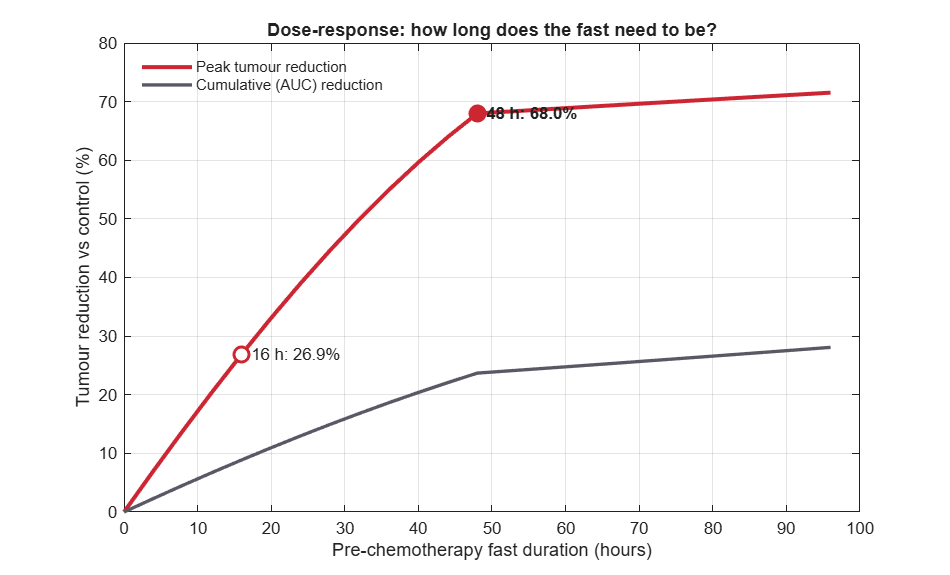


% figure 3: Fast duration sensitivity analysis:

sweepHrs = []; sweepPeak = []; sweepAUC = []; sweepC60 = [];
if runSweep
    % First create empty lists so the variables always exist, even if
    % runSweep is false (they are saved to the results file at the end).

    sweepHrs = 0:4:96;      % start at 0, step by 4, stop at 96
    sweepPeak = zeros(size(sweepHrs));
    sweepAUC  = zeros(size(sweepHrs));
    sweepC60  = zeros(size(sweepHrs));
    
    for i = 1:numel(sweepHrs)
        h = sweepHrs(i);
        % Loop over every fast length 
        % i runs from 1 up to the number of durations 
        % h is the fast length for this pass.

        if h == 0
            [ts,Ys] = runArm(p, Inf, Inf); 
        else
            [ts,Ys] = runArm(p, p.tChemo-h/24, p.tChemo);
        end
        % A 0-hour fast means no fast at all, so use the control settings (Inf).
        % Otherwise the fast starts h/24 days before chemo and ends at chemo.

        Ci = interp1(ts,Ys(:,3),tg);
        sweepPeak(i) = max(100*(Cc-Ci)./Cc);
        sweepAUC(i)  = 100*(1-trapz(tg,Ci)/aucC);
        sweepC60(i)  = Ys(end,3);
    end
    %   sweepPeak : the largest % tumour reduction vs control
    %   sweepAUC  : % reduction in cumulative tumour burden 
    %   sweepC60  : tumour size on the last day

    figure('Color','w','Position',[120 120 760 460]); hold on; box on;
    plot(sweepHrs,sweepPeak,'-','Color',colC,'LineWidth',2.4, ...
         'DisplayName','Peak tumour reduction');
    plot(sweepHrs,sweepAUC,'-','Color',[0.35 0.35 0.40],'LineWidth',2.0, ...
         'DisplayName','Cumulative (AUC) reduction');

    i16 = find(sweepHrs==16); i48 = find(sweepHrs==48);
    plot(16,sweepPeak(i16),'o','MarkerSize',9,'MarkerFaceColor','w', ...
         'Color',colC,'LineWidth',1.8,'HandleVisibility','off');
    plot(48,sweepPeak(i48),'o','MarkerSize',9,'MarkerFaceColor',colC, ...
         'Color',colC,'LineWidth',1.8,'HandleVisibility','off');
    % find(sweepHrs==16) returns the POSITION in the list where the value is 16. 
    % We use those positions to pick out and highlight the 16 h and 48 h points.

    text(16,sweepPeak(i16),sprintf('  16 h: %.1f%%',sweepPeak(i16)),'FontSize',10);
    text(48,sweepPeak(i48),sprintf('  48 h: %.1f%%',sweepPeak(i48)),'FontSize',10,'FontWeight','bold');
    xlabel('Pre-chemotherapy fast duration (hours)');
    ylabel('Tumour reduction vs control (%)');
    title('Dose-response: how long does the fast need to be?','FontWeight','bold');
    grid on; set(gca,'GridAlpha',0.12); legend('Location','northwest','Box','off');
end


save('tnbc_results.mat','p','tCon','Ycon','tFas','Yfas','fastStart','fastEnd', ...
     'sweepHrs','sweepPeak','sweepAUC','sweepC60');
fprintf('Saved tnbc_results.mat  ->  now run: tnbc_visualisations\n');

Saved tnbc_results.mat  ->  now run: tnbc_visualisations



%  NOTE ON THE DSR SWITCH 
%  With useDSR = false the only thing the fast removes is the GROWTH term
%  Because lambda_C = 3*lambda_H, the tumour loses 3x more
%  growth than healthy tissue does - so selectivity is real,
%  but it is bounded by how much growth there was to remove.
%
%  Setting useDSR = true encodes Differential Stress Resistance explicitly: 
%  healthy cells downshift into protected maintenance (mu_H falls) 
%  while metabolically inflexible TNBC cells cannot, and
%  enter oxidative stress / apoptosis (mu_C rises). 


%  PART 2  -  VISUALISATIONS


if ~isfile('tnbc_results.mat')
    error('tnbc_results.mat not found. Run tnbc_fasting_trial first.');
end
load('tnbc_results.mat');

colH = [0.10 0.45 0.75];
colC = [0.80 0.15 0.20];



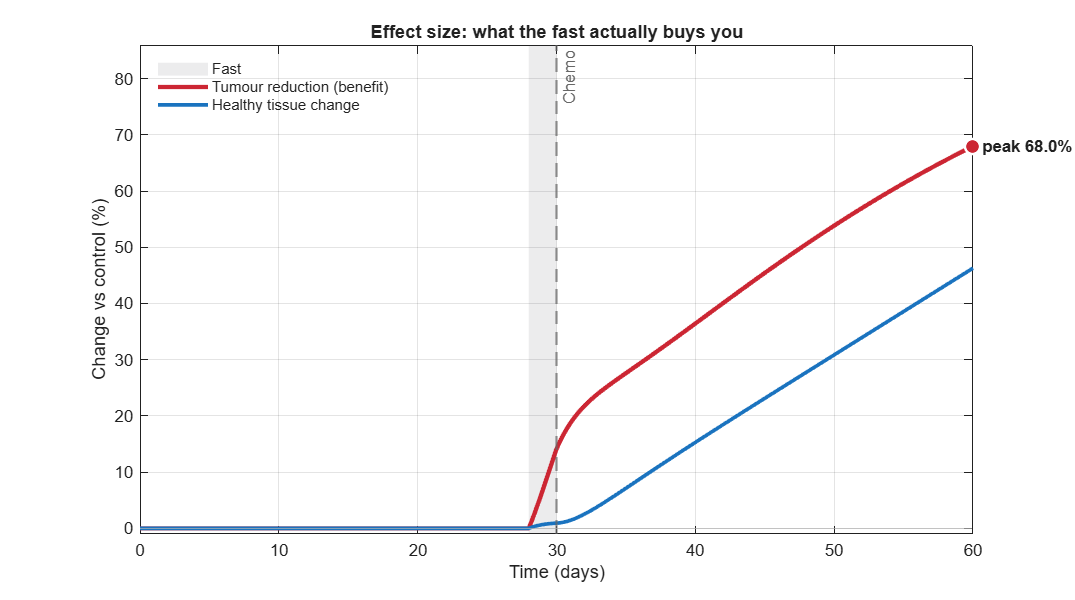


%  figure 2: Effect on size over time
%  Plots the difference between arms rather than the arms themselves.
%  this is the figure that actually shows the effect size.

tf2 = linspace(0,p.tEnd,4000)';
Cc2 = interp1(tCon,Ycon(:,3),tf2); Cf2 = interp1(tFas,Yfas(:,3),tf2);
Hc2 = interp1(tCon,Ycon(:,2),tf2); Hf2 = interp1(tFas,Yfas(:,2),tf2);

sepC = 100*(Cc2-Cf2)./Cc2;
sepH = 100*(Hf2-Hc2)./Hc2;
% sepC: % less tumour in the fasted arm than control 
% sepH: % more healthy tissue in the fasted arm than control

figure('Color','w','Position',[120 120 860 480]); hold on; box on;

yl = [min([sepC;sepH])-1, max(sepC)*1.25+1];
patch([fastStart fastEnd fastEnd fastStart],[yl(1) yl(1) yl(2) yl(2)], ...
      [0.25 0.25 0.30],'FaceAlpha',0.10,'EdgeColor','none','DisplayName','Fast');
xline(p.tChemo,'--','Chemo','Color',[0.4 0.4 0.4],'LineWidth',1.3,'HandleVisibility','off');

yline(0,'-','Color',[0.7 0.7 0.7],'HandleVisibility','off');
plot(tf2,sepC,'-','Color',colC,'LineWidth',2.6,'DisplayName','Tumour reduction (benefit)');
plot(tf2,sepH,'-','Color',colH,'LineWidth',2.2,'DisplayName','Healthy tissue change');

% Find the largest tumour reduction (mx) and where it occurs (im)
[mx,im] = max(sepC);
plot(tf2(im),mx,'o','MarkerSize',9,'MarkerFaceColor',colC,'MarkerEdgeColor','w', ...
     'LineWidth',1.5,'HandleVisibility','off');
text(tf2(im),mx,sprintf('  peak %.1f%% (Day %.1f)',mx,tf2(im)),'FontSize',10,'FontWeight','bold');
xlabel('Time (days)'); ylabel('Change vs control (%)');
title('Effect size: what the fast actually buys you','FontWeight','bold');
xlim([0 p.tEnd]); ylim(yl); grid on; set(gca,'GridAlpha',0.12);
legend('Location','northwest','Box','off');



%  LOCAL FUNCTIONS 

function [t, Y] = runArm(p, fastStart, fastEnd)
% runArm : run one arm of the trial
%   Inputs : p (all parameters), fastStart, fastEnd (days of the fast)
%   Outputs: t (times) and Y (columns G, H, C)

% Integrates the model in SEGMENTS split at every discontinuity.
% This matters: I(t) and the chemo term are step functions, and ode45
% will step straight over a 48-hour gap if you hand it the whole 
% [0 60] interval at once. Segmenting makes the solution exact
% at the switch points instead of solver-dependent.

    y0 = [p.G0; p.H0; p.C0];

    bp = [0, p.tChemo, p.tEnd];
    if isfinite(fastStart), bp = [bp, fastStart, fastEnd]; end
    bp = unique(bp);
    bp = bp(bp >= 0 & bp <= p.tEnd);
    % bp = breakpoints
    %   0 = start,  tChemo = chemo switches on,  tEnd = finish.
    % If there is a fast (fastStart is a real number, tested with isfinite),
    % also add the days the fast starts and ends.

    opts = odeset('RelTol',1e-8,'AbsTol',1e-10,'NonNegative',[1 2 3]);
    %   RelTol / AbsTol : how accurate the answer must be 
    %   NonNegative     : cells and glucose can never go below zero


    t = []; Y = [];
    for s = 1:numel(bp)-1
    % numel(bp)-1 = the number of segments. 
    % Each segment ends exactly where the next begins

        span = [bp(s) bp(s+1)];
        if diff(span) <= 0, continue; end
        % span = [start day, end day] of this segment. 

        [ts,Ys] = ode45(@(tt,yy) odefun(tt,yy,p,fastStart,fastEnd), span, y0, opts);
        % Inputs: the rule function, the time span, the starting values y0, and the options.
        % @(tt,yy) odefun(tt,yy,p,fastStart,fastEnd) is an anonymous function that
        % hands the extra inputs (p, fastStart, fastEnd) to our rule function
        % odefun, because ode45 itself only supplies time and state.
        % Outputs: ts = times, Ys = G, H, C at those times.

        if s > 1, ts(1) = []; Ys(1,:) = []; end   % drop duplicated knot
        t = [t; ts]; Y = [Y; Ys];                 %#ok<AGROW>
        y0 = Ys(end,:)';
    end
end

% Each new segment starts at the same time the last one ended, so its first
% row would be a duplicate. ts(1) = [] deletes the first element for every 
% segment after the first.
% Then stick the new rows underneath the old ones with [old; new].
% y0 becomes the last row of this segment (Ys(end,:), transposed to
% a column with ') so the next segment continues from where this one ended.



function dydt = odefun(t, y, p, fastStart, fastEnd)
    % odefun : the three equations.
    % ode45 calls this over and over. Given the time t and the current state
    % y = [G; H; C], it must return dydt = the RATE OF CHANGE of each of them.
    % The other inputs (p, fastStart, fastEnd) are the parameters and fast days.

    G = y(1); H = y(2); C = y(3);

    fasting = (t >= fastStart) && (t < fastEnd);
    I       = p.I_base * (~fasting);              % feeding function I(t)
    chemoOn = (t >= p.tChemo);
    % A comparison gives true or false, and && means both must be true.
    % I(t) = the feeding rate: p.I_base multiplied by (~fasting). "~" means NOT,
    % so while fasting ~fasting = 0 and glucose supply is cut to zero;
    % otherwise it is 1 and the normal supply continues.
    % chemoOn is true once the day reaches the chemo start.

    muH = p.mu_H;  muC = p.mu_C;
    if p.useDSR && fasting                        % optional DSR extension
        muH = muH * p.dsrH;
        muC = muC * p.dsrC;
    end
    % Start from the normal natural death rates. If the DSR switch is on AND we
    % are fasting, multiply them: 
    % healthy cells x0.5, cancer cells x4. 
    % Outside the fast they stay unchanged.

    isExperiment = isfinite(fastStart); 
    % Choose the chemo kill rates
    %   before Day 30             -> 0 for both
    %   Day 30 on, CONTROL arm    -> p.killH and p.killC
    %   Day 30 on, EXPERIMENT arm -> slides from those values to 0.01 / 0.12
    % The experiment arm is recognised by a real fastStart; control has Inf.
    % "Sensitised chemo" assumption: fasting makes chemo gentler on healthy cells, stronger on the tumour.
    % f = fast length / p.fastHrs, capped at 1 (0 = no fast, 1 = full 48 h fast; a 16 h fast gives f = 1/3).

    if chemoOn
        if isExperiment
            % EXPERIMENT: Sensitized Chemotherapy 
            f  = min((fastEnd - fastStart)/(p.fastHrs/24), 1);   % 0 = no fast, 1 = full-length fast
            kH = p.killH + f*(0.01 - p.killH);   % slides from 0.02 (no fast) down to 0.01 (full fast)
            kC = p.killC + f*(0.12 - p.killC);   % slides from 0.08 (no fast) up to 0.12 (full fast)
        else
            % CONTROL: Standard Care Baseline
            kH = p.killH;
            kC = p.killC;
        end
    else
        % Before Day 30, no chemo is applied
        kH = 0;
        kC = 0;
    end



    % The "logistic" crowding factor. When there are few cells (H + C is small)
    % comp is close to 1 and growth is unrestricted. As H + C nears K it drops
    % towards 0 and growth stops. If H + C exceeds K it turns negative.
    comp = 1 - (H + C)/p.K;                       % shared spatial limitation

    % THE THREE EQUATIONS, one per line:
    % dG  = supply in
    %     - glucose used by healthy cells 
    %     - glucose used by cancer cells  
    %     - natural clearance             
    % dH  = growth - natural death - chemo 
    % dC  = the same form, with cancer's own rates.
    dG = I - p.alpha_H*G*H - p.alpha_C*G*C - p.delta_G*G;
    dH = p.lambda_H*G*H*comp - muH*H - kH*H;
    dC = p.lambda_C*G*C*comp - muC*C - kC*C;

    dydt = [dG; dH; dC];
end

